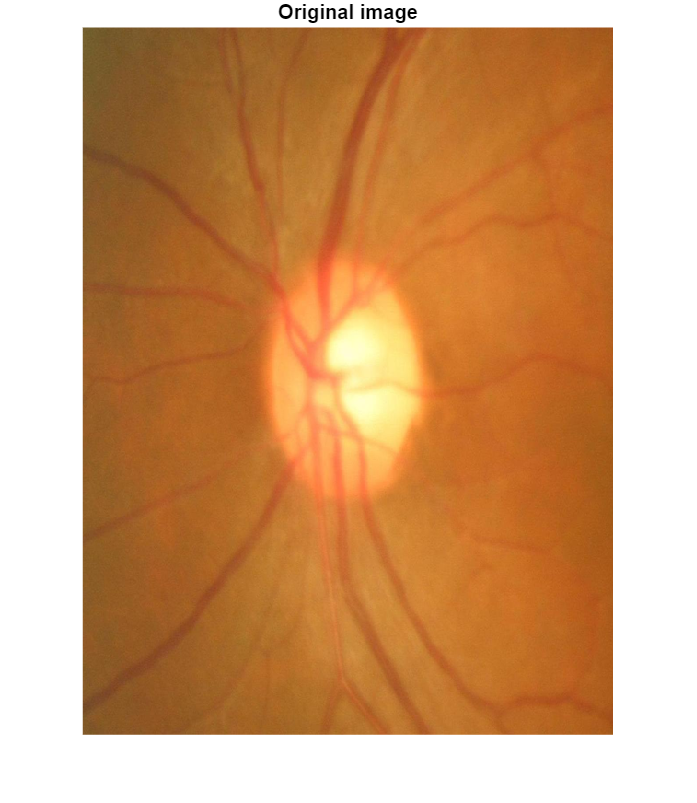

clc;
clear all;
close all;
img_path = fullfile('OD_zoom_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('..','data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
k=8;%cambia esto



%%%%%%%%%%%%%%preprocessing%%%%%%%%%%%%%%%%%
a= imread(string(fullfile(img_path, T{k,1})));
b=imresize(a,[768 576]);
figure,
imshow(b);
title('Original image');

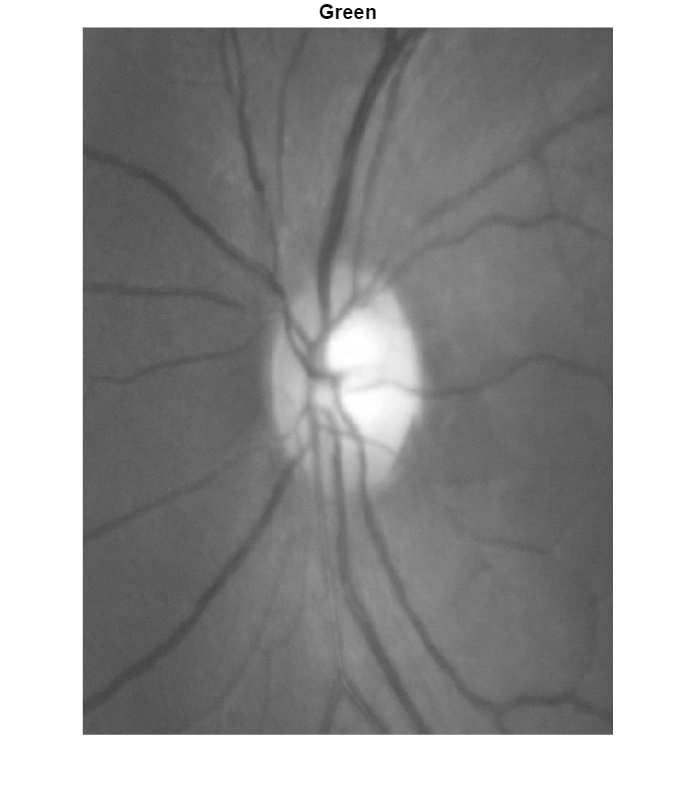


%%%%%%%%%%%%Blood vessel segmentation%%%%%%%%%%%%%%%%%
A=b(:,:,2);
figure;imshow(A);title('Green');

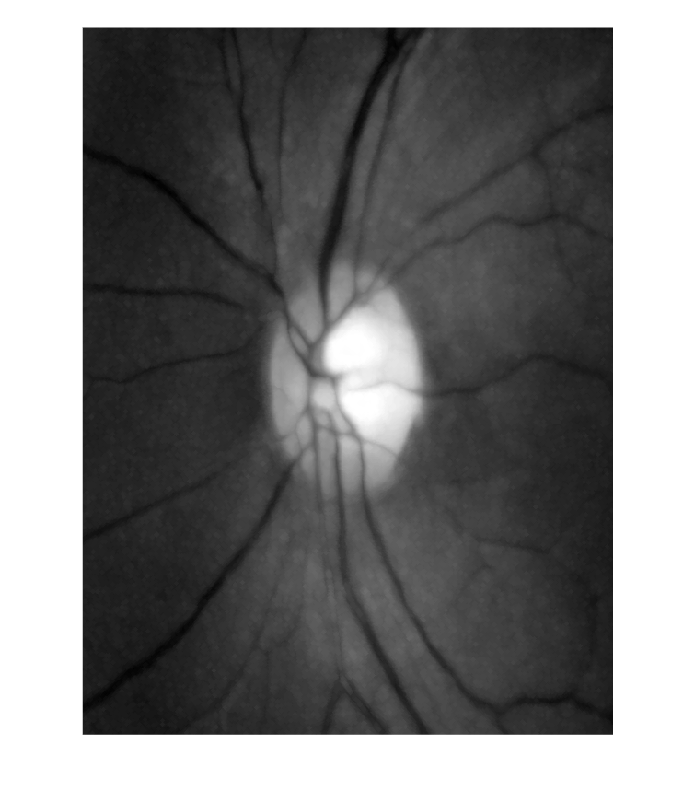

B1 = strel('disk',2);
B2= strel('disk',6);
Dilated=imdilate(A,B1);
figure;imshow(Dilated,[]);

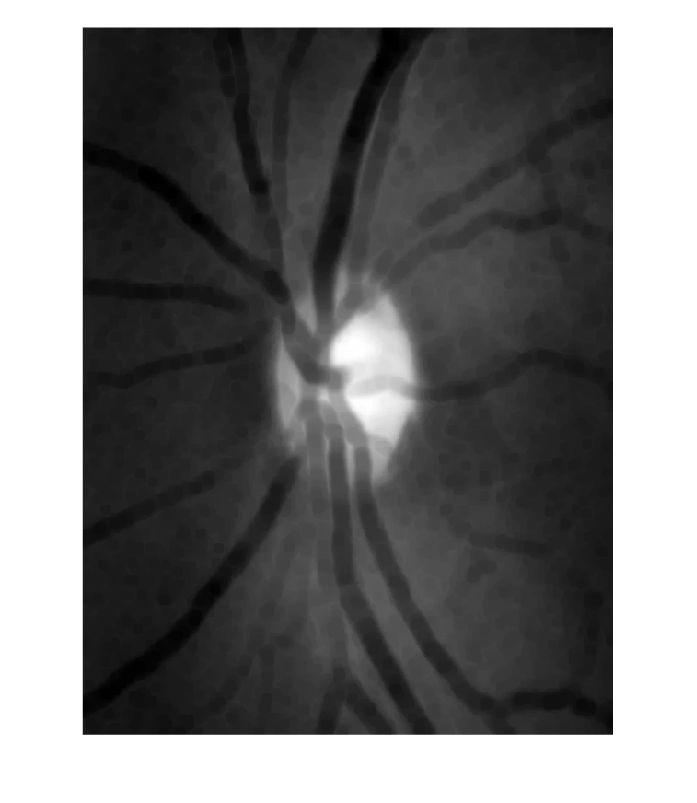

Eroded=imerode(A,B2);
figure;imshow(Eroded,[]);

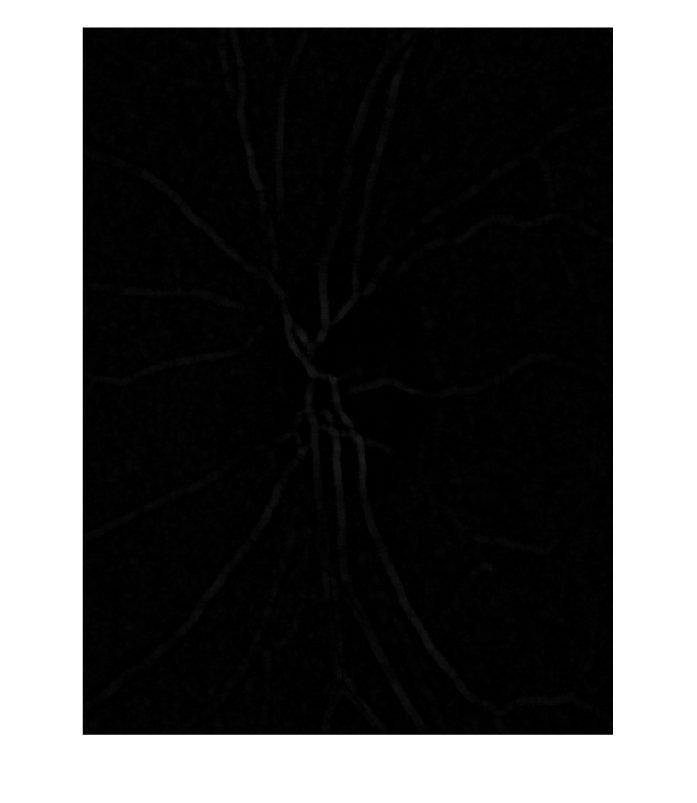


X=imdilate(A,B2);
X1=imerode(X,B2);


Y=imdilate(A,B1);
Y1=imerode(Y,B1);

C= X1-Y1;
figure;imshow(C);

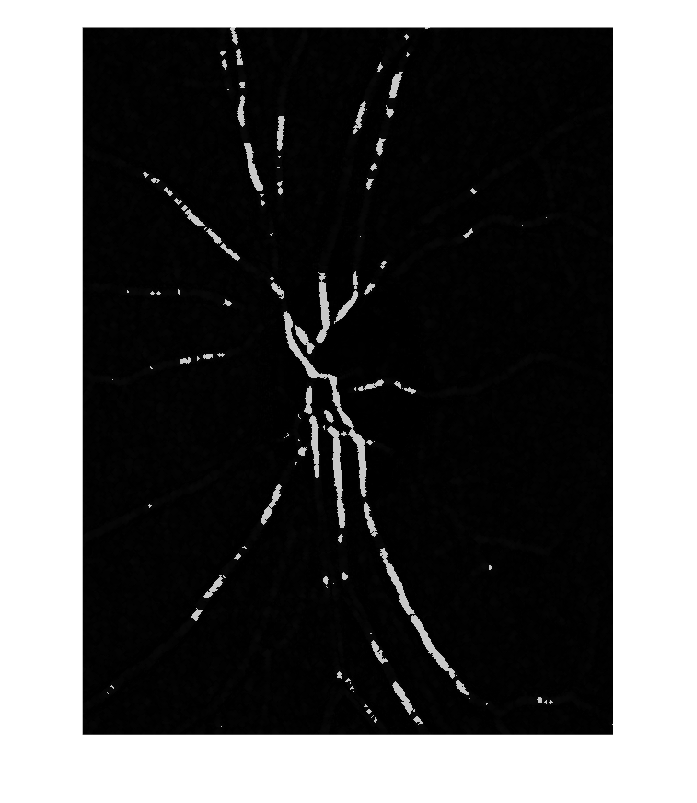

% pixval on;
[r c]=size(C);
for i=1:r
    for j=1:c
        aa=C(i,j);
        if aa > 8
            C(i,j)=200;
        end
    end
end
   figure;imshow(C); 

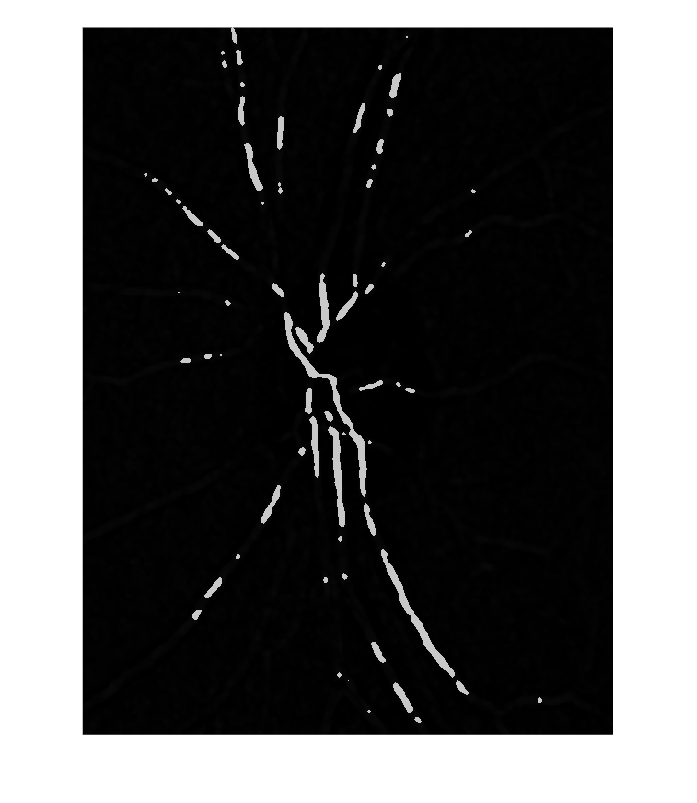

F=medfilt2(C,[3 3]);
U=medfilt2(F,[5 5]);
figure;imshow(U);

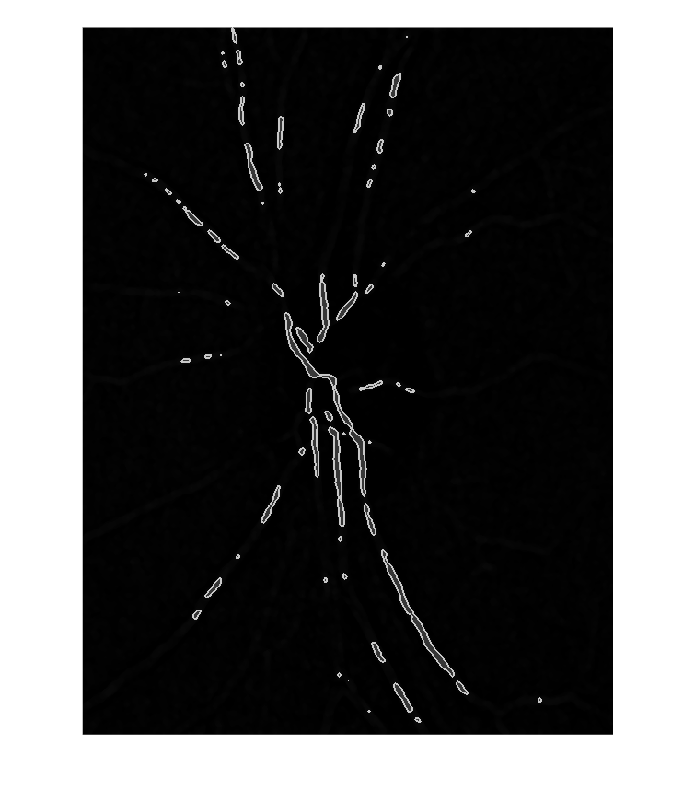

%%%%%%%%%%% Morphological thinning operation%%%%%%%%%%%%%

T=(U-(imerode(U,B1)- imerode(imcomplement(U),B1)));
figure;imshow(T);

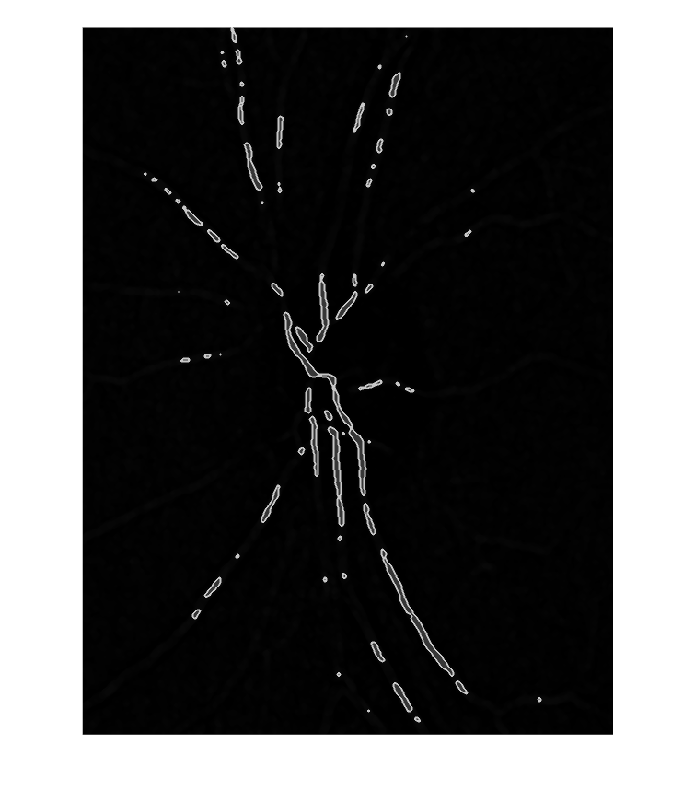

Filtered=medfilt2(T,[2 2]);
figure;imshow(Filtered);

cap=U>100;
capilares=double(cap);
unique(capilares)

ans =      0
     1


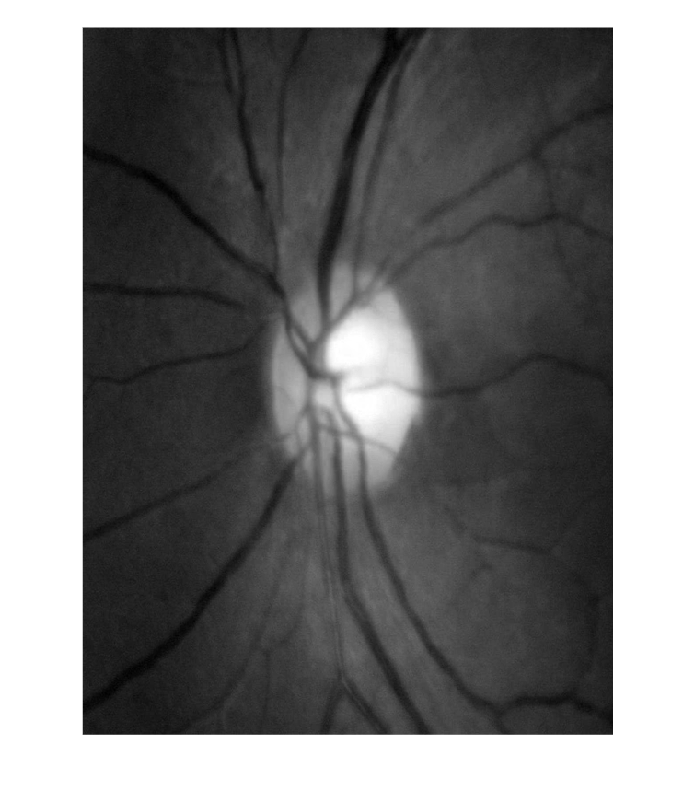

no_capilares=1-capilares;
G=double(b(:,:,2));
imshow(G,[]);

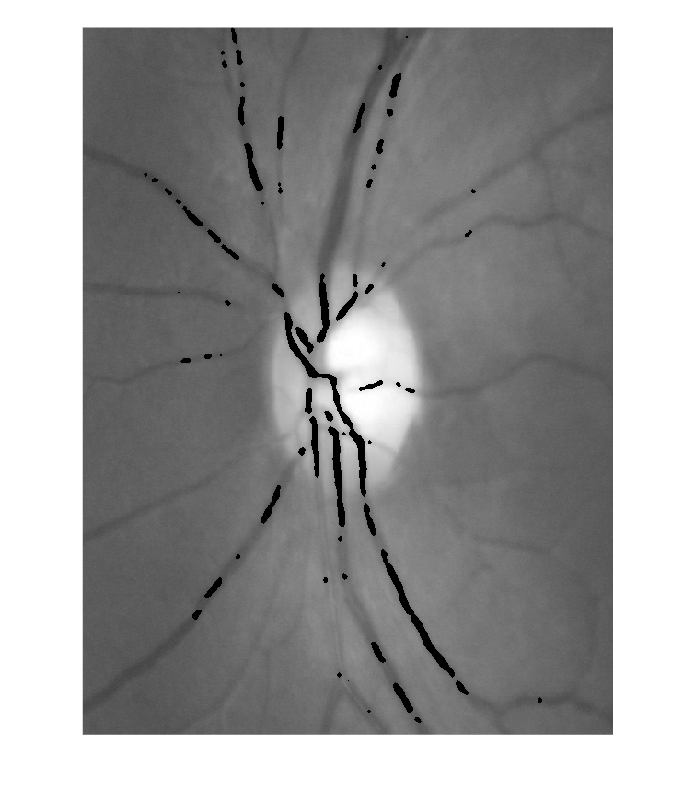

G_sinCaps=G.*no_capilares;
imshow(G_sinCaps,[]);

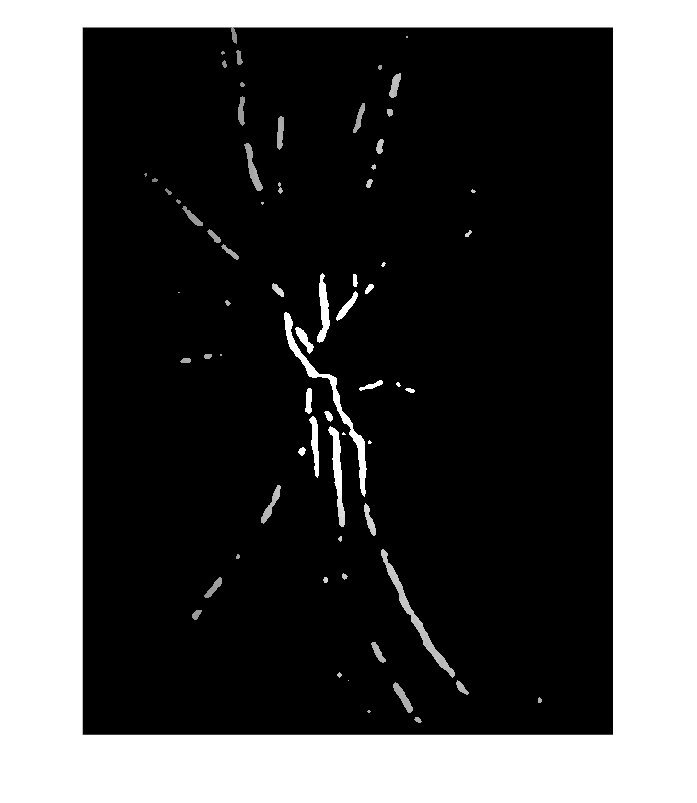

           
R=double(b(:,:,1));
capsEnR=R.*capilares;
imshow(capsEnR,[]);

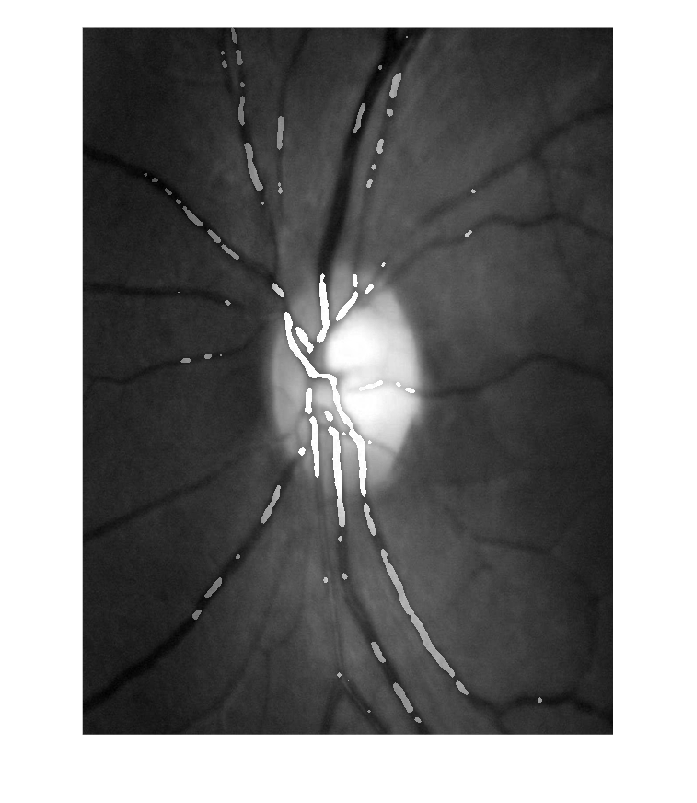


G_procesada=G_sinCaps+capsEnR;
imshow(G_procesada,[]);

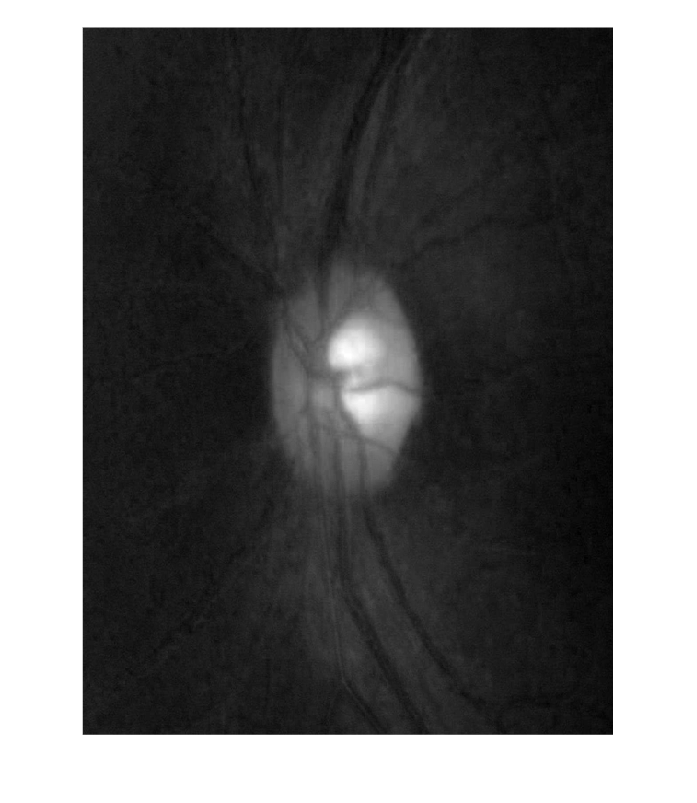


B=double(b(:,:,3));
imshow(B,[]);

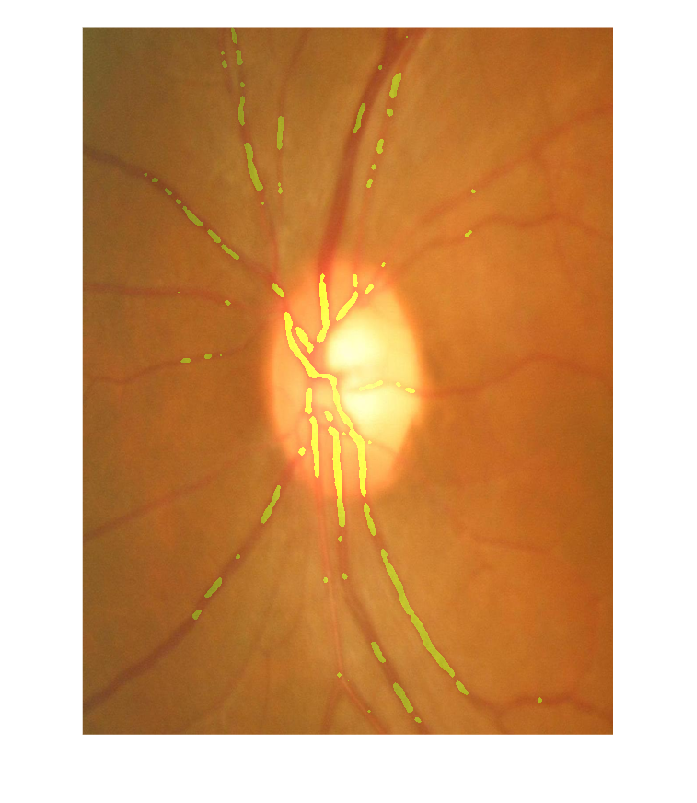

RGB = cat(3, R, G_procesada, B);
RGB=uint8(RGB);
imshow(RGB,[]);